# **Transfer Learning using AlexNet and Dog Breed Classifier Dataset**

You will need to have modified dataset.

- Download the "Dog Breed Identification" dataset from (https://www.kaggle.com/c/dog-breed-identification/data)

- Run "ModifyDataset.mlx" script to modify the dataset into directory wise categories

# Train

## Set up testing data

rootFolder = 'test';

LabelData = readtable('.\labels.csv', 'Format', '%C%C');
BreedLabels = string(transpose(table2cell(unique(LabelData(:,'breed')))));

BreedCount = numel(BreedLabels)

BreedCount = 120


testDS = imageDatastore(fullfile(rootFolder, BreedLabels), 'LabelSource', 'foldernames');
testDS.ReadFcn = @readFunctionTrain;

## Import GoogLeNet trained with Transfer Learning

Importing trained network for some manual validation and results.

AlexNet_convnet = trainedNetwork_1;

## Test classifer

[labels,err_test] = classify(AlexNet_convnet, testDS, 'MiniBatchSize', 64);

## Determine overall accuracy

AlexNet_confMat = confusionmat(testDS.Labels, labels);
AlexNet_confMat = AlexNet_confMat./sum(AlexNet_confMat,2);
OverallAccuracy = mean(diag(AlexNet_confMat))

OverallAccuracy = 0.9021

BreedAcc = diag(AlexNet_confMat).';
int_confMat = int64(AlexNet_confMat .* 10000)

int_confMat = 120×120 int64 matrix
   9125      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0    125    250      0      0    125      0      0    125      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0
      0   9569      0      0      0      0      0      0      0      0      0      0     86      0      0      0      0      0      0      0      0      0      0     86      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0
      0      0   9535      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0    116      0      0      0      0      0      0      0    

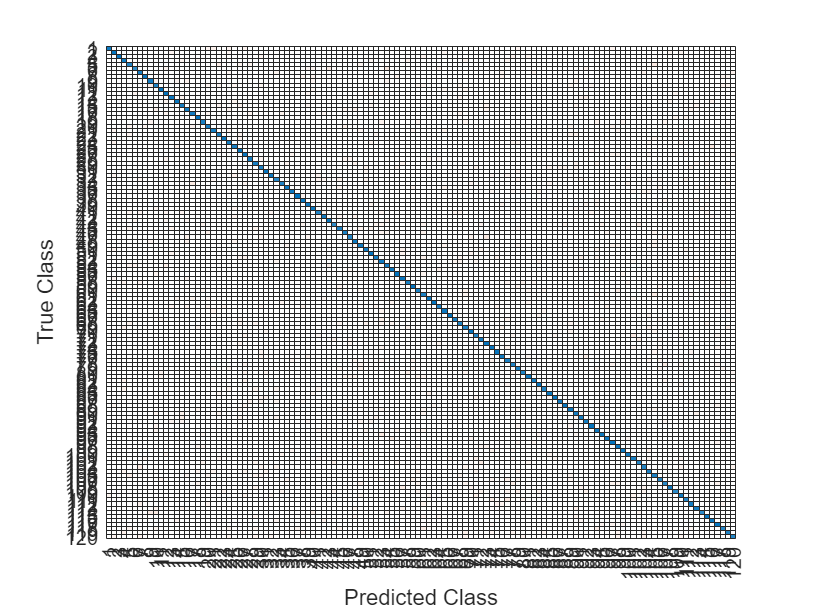

confusionchart(int_confMat)